clear
TOF_or_Distance="Distance"

TOF_or_Distance = "Distance"

g=9.81;
RopeLength_ft=19;
COM_height_above_floor_ft=2;   % COM height above floor at theta=0;
ApexHeight_ft=RopeLength_ft+COM_height_above_floor_ft;
A=ApexHeight_ft*12*2.54/100;    % A is in meters
Platform_height_ft=20;
initial_height=Platform_height_ft*12*2.54/100;   % initial_height is in meters

costhta0d=(ApexHeight_ft-Platform_height_ft)/RopeLength_ft;
thta0d=-acosd(costhta0d);
thta0=deg2rad(thta0d);

iflag=0;
N=1000;  trelease=linspace(1,20,N);xmax=zeros(N,1);
for n=1:N
    tr=trelease(n);
    xmax(n)=MaxDis(A,g,tr,thta0,iflag);
end

[v,n]=max(xmax);
trEst=trelease(n);tofEst=trEst;

% plot(trelease,xmax);grid on;
% hold on;plot(trelease(n),xmax(n),'*r');hold off

switch TOF_or_Distance
    case "TOF"
        xmaxpos=@(tr)-MaxTOF(A,g,tr,thta0);
    case "Distance"
        xmaxpos=@(tr)-MaxDis(A,g,tr,thta0,iflag);
    otherwise
        disp("error in case variable - default to TOF ")
        xmaxpos=@(tr)-MaxTOF(A,g,tr,thta0,iflag);
end

[trSoln,~]=fminsearch(xmaxpos,tofEst);

fprintf(" Height of Trapeze (meters) = %6.4f \n",A)

 Height of Trapeze (meters) = 6.4008 


fprintf(" Initial Angle (deg) = %6.4f \n",thta0d)

 Initial Angle (deg) = -86.9830 


fprintf(" Initial Height (meters) = %6.4f \n",initial_height)

 Initial Height (meters) = 6.0960 


fprintf(" Time before release (sec) %6.4f \n",trSoln)

 Time before release (sec) 13.7536 


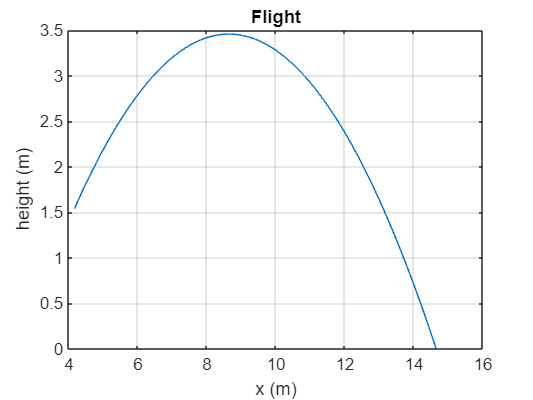

 Time of flight (sec) 1.46 



iflag=1;
xmax=MaxDis(A,g,trSoln,thta0,iflag);

fprintf(" Flight distance (meters)= %6.4f \n",xmax)

 Flight distance (meters)= 14.6437 


function tof=MaxTOF(A,g,tr,thta0)
[~,Ts]=TrapezeEquation(A,g,tr,thta0);
[xend,zend,xendp,zendp]=LaunchParams(A,Ts);
[t,x,z]=InFlight(xend,zend,xendp,zendp,g);
tof=max(t(z<A))-min(t(z<A));
end

function xmax=MaxDis(A,g,tr,thta0,iflag)
[~,Ts]=TrapezeEquation(A,g,tr,thta0);
[xend,zend,xendp,zendp]=LaunchParams(A,Ts);
[t,x,z]=InFlight(xend,zend,xendp,zendp,g);
if iflag==1
    plot(x(z<A),A-z(z<A));grid on;title('Flight');xlabel("x (m)");ylabel("height (m)");
    fprintf(' Time of flight (sec) %4.2f \n',max(t(z<A))-min(t(z<A)))
end
xmax=max(x(z<A));
end

function [ts,Ts]=TrapezeEquation(A,g,tr,thta0)
dthtadt=@(t,thta,thtap)thtap;
dthtapdt=@(t,thta,thtap)-g/A*sin(thta);
DT=@(t,T)[dthtadt(t,T(1),T(2)) ; dthtapdt(t,T(1),T(2))];
T0=[thta0;0];
[ts,Ts]=ode45(DT,[0,tr],T0);
end

function [xend,zend,xendp,zendp]=LaunchParams(A,Ts)
Tend=Ts(end,1);
TPend=Ts(end,2);
xend=A*sin(Tend);
zend=A*cos(Tend);
xendp=A*cos(Tend).*TPend;
zendp=-A*sin(Tend).*TPend;
end

function [ts,xs,zs]=InFlight(xend,zend,xendp,zendp,g)
ts=linspace(0,10,10000);
xs=xend+ts*xendp;
zs=zend+ts*zendp+0.5*g*ts.^2;
end